R1 = 25

R1 = 25

R2 = 40

R2 = 40

R3 = 20

R3 = 20

R4 = 10

R4 = 10

G1 = 1/R1

G1 = 0.0400

G2 = 1/R2

G2 = 0.0250

G3 = 1/R3

G3 = 0.0500

G4 = 1/R4

G4 = 0.1000

Iq1 = 4

Iq1 = 4

Iq2 = 2

Iq2 = 2

Uq = 12

Uq = 12

Iq3 = Uq/R3

Iq3 = 0.6000



I1_1 = Iq1*(R1234/R1)

Unrecognized function or variable 'R1234'.

I34_1 = Iq1-I1_1
I3_1 = I34_1*(R34/R3)
I4_1 = I34_1*(R34/R4)
I2_1 = I34_1

I2_2 = Iq2*(R1234/R2)
I34_2 = Iq2-I2_2 
I3_2 = I34_2*(R34/R3)
I4_2 = I34_2*(R34/R4)
I1_2 = I34_2

R12 = R1+R2
G12 = 1/R12
R1234_3 = 1/(G12+G3+G4)
I2_3 = Iq3*(R1234_3/R12)
I1_3 = I2_3
I3_3= Iq3*(R1234_3/R3)
I4_3 = Iq3*(R1234_3/R4)

I1 = I1_1+I1_2-I1_3
I2 = I2_1+I2_2+I2_3
I3 = I3_1-I3_2-I3_3
I4 = I4_1-I4_2-I4_3


## Maschen und Knotengleichungen

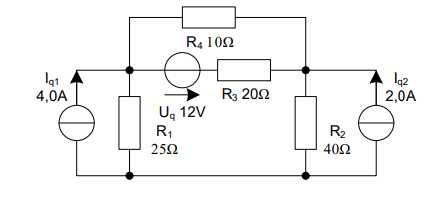

clear
R1 = 25
R2 = 40
R3 = 20
R4 = 10
Iq1 = 4
Uq1 = Iq1*R1
Iq2 = 2
Uq2 = Iq2*R2
Uq3 = 12
Iq3 = Uq3/R3


A = [ R1    -R2     R3    0 
       0      0    -R3   R4
       1      0    -1    -1
       0      1     1     1  ]

U = [ Uq1-Uq2-Uq3; Uq3; 0; 0 ]

I=A\U

U1 = Uq1 - R1*I(1)
U2 = Uq2 - R2*I(2)
U3 = R3*I(3)
U4 = R4*I(4)

I1 = Iq1-I(1)
I2 = Iq2-I(2)


I1 = U1/R1
I2 = U2/R2
I3 = U3/R3
I4 = U4/R4




## Rep

%Lösung mit Maschenstromverfahren
R1=25,R2=40,R3=20,R4=10,Iq1=4,Iq2=2,Uq3=12

format longeng

%Umwandlung der Stromquellen in Spannungsquellen
Uq1ers=Iq1*R1
R1ers=R1

Uq2ers=Iq2*R2
R2ers=R2

% Widerstandsmatrix

ZZ = [ R1ers+R2ers+R3       -R3 
             -R3           R3+R4 ]

% Spannungsquelle wird addiert, wenn Spannungspfeil entgegengesetzt läuft
UU = [ Uq1ers-Uq3-Uq2ers 
              Uq3       ] 

IIM = ZZ\UU

% Berechnung der Ströme
IR1=Iq1-IIM(1)
IR2=IIM(1)+Iq2
IR3=IIM(1)-IIM(2)
IR4=IIM(2)

U1=IR1*R1
U2=IR2*R2
U3=IR3*R3
U4=IR4*R4

%Knotepotentialverfahren
%Umwandlung der Quelle
Iq3ers=Uq3/R3
R3ers = R3

YY = [1/R1+1/R3ers+1/R4          -1/R3ers-1/R4        
        -1/R3ers-1/R4             1/R2+1/R3ers+1/R4]

II = [ Iq1+Iq3ers 
        Iq2-Iq3ers]

UUK = YY\II


## Mehrtore

% Matrizen T und Pi
clear
R1=5,R2=3,C1=6e-6,C2=4e-6,L1=3e-3,L2=7e-3,f=50

R1 = 5

R2 = 3

C1 = 6.0000e-06

C2 = 4.0000e-06

L1 = 0.0030

L2 = 0.0070

f = 50

%syms R1 R2 C1 C2 L1 L2 w
w = 2*pi*f

w = 314.1593


AR1 = [1    R1
       0    1]

AR1 =      1     5
     0     1



AC1 =  [1               0  
         1j*w*C1        1]

AC1 =    1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0019i   1.0000 + 0.0000i



AL1 = [1    1j*w*L1
       0       1   ]

AL1 =    1.0000 + 0.0000i   0.0000 + 0.9425i
   0.0000 + 0.0000i   1.0000 + 0.0000i



A1 = AR1*AC1*AL1 

A1 =    1.0000 + 0.0094i   4.9911 + 0.9425i
   0.0000 + 0.0019i   0.9982 + 0.0000i


%expand(A1)

AR2 = [1      R2
       0      1]

AR2 =      1     3
     0     1



AC2 = [ 1   0   
        1j*w*C2  1]

AC2 =    1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0013i   1.0000 + 0.0000i



AL2 = [ 1            0
        1/(1j*w*L2)  1]

AL2 =    1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.4547i   1.0000 + 0.0000i



A2 = AC2*AR2*AL2

A2 =    1.0000 - 1.3642i   3.0000 + 0.0000i
   0.0017 - 0.4535i   1.0000 + 0.0038i



Ages = A1*A2

Ages =    1.4488 - 3.6165i   7.9876 + 0.9896i
   0.0043 - 0.4508i   0.9982 + 0.0094i



A = 1/Ages(1,1)

A = 0.0955 + 0.2383i








%Z1 = A
%subplot(2,1,1);
%plot(real(Z1),imag(Z1))
%nyquist(real(Z1),imag(Z1))
%grid;
%subplot(2,1,2);
%plot(real(G1),imag(G1))
%grid;


## TF

clear
%expand(Ages)

R = 1; L = 1; C = 1;
G = tf([1/(R*C) 0],[1 1/(R*C) 1/(L*C)])

G =
 
       s
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



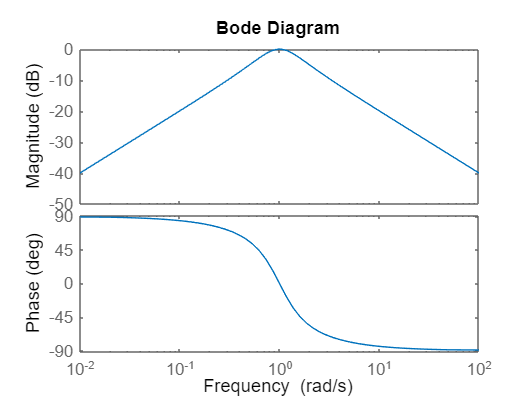


bode(G)

## Aufgabe 5

clear

f=1:1:10000

f =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


w=2*pi*f

w = 	1.0e+04 *

    0.0006    0.0013    0.0019    0.0025    0.0031    0.0038    0.0044    0.0050    0.0057    0.0063    0.0069    0.0075    0.0082    0.0088    0.0094    0.0101    0.0107    0.0113    0.0119    0.0126    0.0132    0.0138    0.0145    0.0151    0.0157    0.0163    0.0170    0.0176    0.0182    0.0188    0.0195    0.0201    0.0207    0.0214    0.0220    0.0226    0.0232    0.0239    0.0245    0.0251    0.0258    0.0264    0.0270    0.0276    0.0283    0.0289    0.0295    0.0302    0.0308    0.0314



R2 = 3, L2 = 7e-3, C2 = 4e-6

R2 = 3

L2 = 0.0070

C2 = 4.0000e-06



Z= 1./((j*w*C2)+1./(R2+j*w*L2))

Z = 	1.0e+02 *

   0.0300 + 0.0004i   0.0300 + 0.0009i   0.0300 + 0.0013i   0.0300 + 0.0018i   0.0300 + 0.0022i   0.0300 + 0.0026i   0.0300 + 0.0031i   0.0300 + 0.0035i   0.0300 + 0.0039i   0.0300 + 0.0044i   0.0300 + 0.0048i   0.0300 + 0.0053i   0.0300 + 0.0057i   0.0300 + 0.0061i   0.0300 + 0.0066i   0.0300 + 0.0070i   0.0300 + 0.0074i   0.0300 + 0.0079i   0.0300 + 0.0083i   0.0300 + 0.0088i   0.0300 + 0.0092i   0.0300 + 0.0096i   0.0300 + 0.0101i   0.0300 + 0.0105i   0.0300 + 0.0109i   0.0300 + 0.0114i   0.0300 + 0.0118i   0.0301 + 0.0123i   0.0301 + 0.0127i   0.0301 + 0.0131i   0.0301 + 0.0136i   0.0301 + 0.0140i   0.0301 + 0.0145i   0.0301 + 0.0149i   0.0301 + 0.0153i   0.0301 + 0.0158i   0.0301 + 0.0162i   0.0301 + 0.0167i   0.0301 + 0.0171i   0.0301 + 0.0175i   0.0301 + 0.0180i   0.0301 + 0.0184i   0.0301 + 0.0189i   0.0301 + 0.0193i   0.0301 + 0.0197i   0.0301 + 0.0202i   0.0301 + 0.0206i   0.0302 + 0.0211i   0.0302 + 0.0215i   0.0302 + 0.0219i


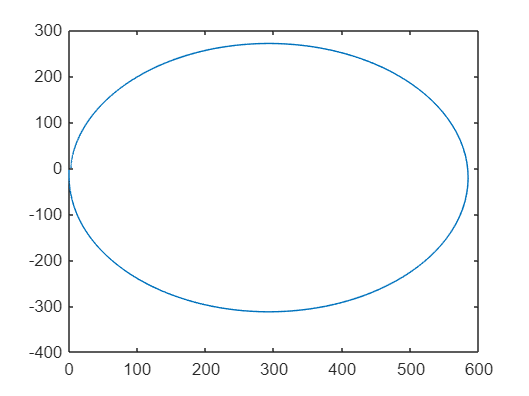

Error using subplot (line 146)
Unknown command option.

plot(real(Z), imag(Z))

grid

%axis ([0,600,-350,350])
%axis equal


## Aufgabe 5.2

clear

R1 = 5, C1 = 6e-6, L1=3e-3

R1 = 5

C1 = 6.0000e-06

L1 = 0.0030

f=1:1:100000

f =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


w=2*pi*f

w = 	1.0e+05 *

    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0026    0.0027    0.0028    0.0028    0.0029    0.0030    0.0030    0.0031    0.0031



Z = R1+1./(j*w*C1+1./(j*w*L1))

Z = 	1.0e+04 *

   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i   0.0005 + 0.0001i


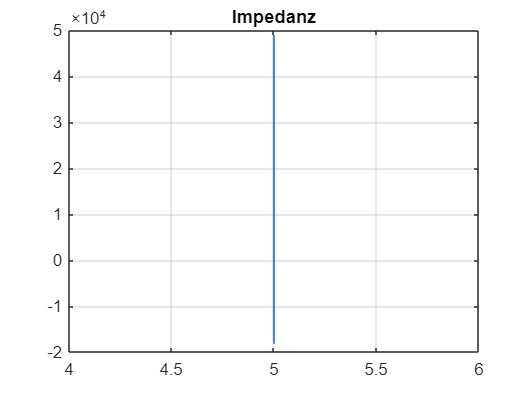

plot(real(Z), imag(Z))
title("Impedanz")
grid


Y = 1./Z

Y =    0.2000 - 0.0008i   0.2000 - 0.0015i   0.2000 - 0.0023i   0.2000 - 0.0030i   0.1999 - 0.0038i   0.1999 - 0.0045i   0.1999 - 0.0053i   0.1998 - 0.0060i   0.1998 - 0.0068i   0.1997 - 0.0075i   0.1997 - 0.0083i   0.1996 - 0.0090i   0.1995 - 0.0098i   0.1994 - 0.0105i   0.1994 - 0.0113i   0.1993 - 0.0120i   0.1992 - 0.0128i   0.1991 - 0.0135i   0.1990 - 0.0143i   0.1989 - 0.0150i   0.1988 - 0.0157i   0.1986 - 0.0165i   0.1985 - 0.0172i   0.1984 - 0.0180i   0.1982 - 0.0187i   0.1981 - 0.0194i   0.1979 - 0.0202i   0.1978 - 0.0209i   0.1976 - 0.0216i   0.1975 - 0.0223i   0.1973 - 0.0231i   0.1971 - 0.0238i   0.1969 - 0.0245i   0.1968 - 0.0252i   0.1966 - 0.0260i   0.1964 - 0.0267i   0.1962 - 0.0274i   0.1960 - 0.0281i   0.1958 - 0.0288i   0.1955 - 0.0295i   0.1953 - 0.0302i   0.1951 - 0.0309i   0.1949 - 0.0316i   0.1946 - 0.0323i   0.1944 - 0.0330i   0.1941 - 0.0337i   0.1939 - 0.0344i   0.1936 - 0.0351i   0.1934 - 0.0358i   0.1931 - 0.0365i


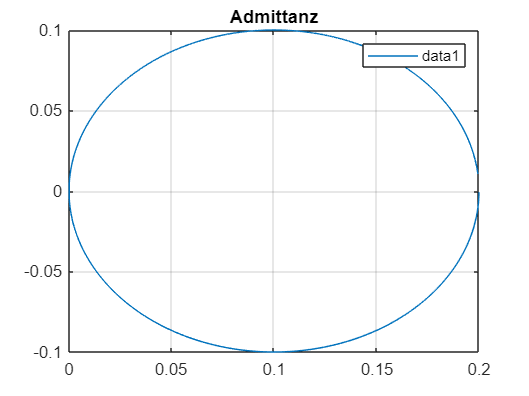

plot(real(Y), imag(Y))
title("Admittanz")
legend()
grid